# Metoda IDW ve 2D

## Otázky

- Jak si mám představit kruhové struktury popsané při shrnutí metody IDW?

## Vliv konfigurace datových bodů

**Úkol 1.    **Vypočtěte váhy $\lambda_i$ pro případ, že jsou v okolí bodu $Z_0$ další tři body $Z_1, Z_2, Z_3$ ve vzdálenostech $r_1 : r_2 : r_3 = 3 : 1 : 2$.  

**Řešení    **Zjistím sumu převrácených hodnot jednotlivých vdáleností $R = \sum 1/r_i^{\alpha = 1}$ a spočtem jednotlivé normalizované váhy $\lambda_i = r_i^{-1} / R$,vyjde nám


$$R = \frac{1}{3 r_2} + \frac{1}{r_2} + \frac{1}{2 r_2} = 

\frac{2r_1 r_3 + 6r_1 r_3 + 3r_1 r_3}{r_1 r_2 r_3} = 

\frac{11(r_1 r_2 r_3)}{6(r_1 r_2  r_3)}  =  \frac{11}{6}.$$
 

% Zjistíme jednotlivé váhy.
R = 11/6

R = 1.8333


% Spočteme jednotlivé váhy.
l1 = (1/3) / R    

l1 = 0.1818

l2 = (1/1) / R

l2 = 0.5455

l3 = (1/2) / R

l3 = 0.2727


% Testuji, že suma vah by měla být rovna přibližně 1.0.
abs(1 - (l1 + l2 + l3)) <= 1e-6

ans = logical
   1


**Úkol 3.    **Doplňte trojici datových bodů o čtvrtý bod, který je poblíž třetího a jehož vzdálenost od počítaného bodu je 2, podobně jako obr. 2.10 v GPI, a zopakujte výpočet vah. Váhy porovnejte s předchozím případem U1. Vyslovte svůj názor.

**Řešení   **$R = \frac{1}{3 r_2} + \frac{1}{r_2} + \frac{1}{2 r_2}  + \frac{1}{2 r_2} = 

\frac{2r_1 r_3 + 6r_1 r_3 + 3r_1 r_3 +  3r_1 r_3}{r_1 r_2 r_3} = 

\frac{14(r_1 r_2 r_3)}{6(r_1 r_2  r_3)}  =  \frac{14}{6}.$

% Zjistíme jednotlivé váhy.
R = 14/6

R = 2.3333


% Spočteme jednotlivé váhy.
l1 = (1/3) / R    

l1 = 0.1429

l2 = (1/1) / R

l2 = 0.4286

l3 = (1/2) / R

l3 = 0.2143

l4 = (1/2) / R

l4 = 0.2143


% Testuji, že suma vah by měla být rovna přibližně 1.0.
abs(1 - (l1 + l2 + l3 + l4)) <= 1e-6

ans = logical
   1


Body se stejnou vzdáleností dostanou stejnou váhu, jak jsou rozložené v prostoru, nehraje roli.

(V knize tomu rozumím, ale nevím proč v v 2.10, když to mám počítat,nejsou tedy zadané vadálenosti, abych si ty váhy sám spočítal, bral jsem to tedy, zase s těmi poměry, jako v minulém příkladě, kdy $r2$ má jednotkovou vzdálenost)

**Úkol 4**

function z = intpol_IDW_2D_1b(xd, yd, zd, x, y, a)

    % interpolace metodou IDW v 1 bode

    nd=length(xd);

    for i=1:nd

       r=sqrt( (x-xd(i))^2 + (y-yd(i))^2 ); % upravíme na euklidovu vzdálenost.

       if r==0

           z=zd(i);

           return

       else

           lam(i)=1/r^a;

       end

    end

    lam=lam/sum(lam);

end    

z=lam*zd';

### **Funkce meshgrid pro generování 2D sítě**

[Xg,Yg] = meshgrid([1:6],[1:4])

Xg =      1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6
     1     2     3     4     5     6


Yg =      1     1     1     1     1     1
     2     2     2     2     2     2
     3     3     3     3     3     3
     4     4     4     4     4     4


Zg = Xg + Yg

Zg =      2     3     4     5     6     7
     3     4     5     6     7     8
     4     5     6     7     8     9
     5     6     7     8     9    10


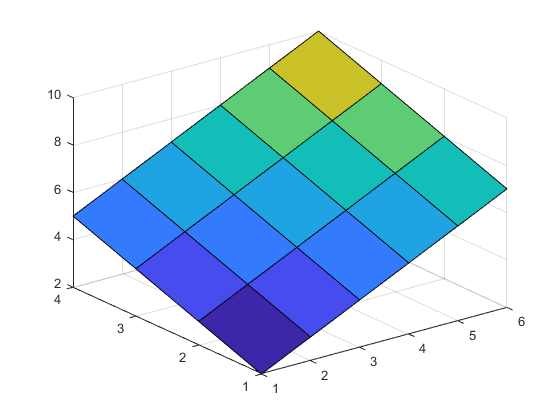

surf(Xg,Yg,Zg)

### Interpolace IDW 2D

intpol_IDW_2D([-2 1 0],[0 0 2],[10 20 30],[-5:3],[-2:4],2).